clc;
clear;

% === Drone Simulation Parameters ===
dt = 0.01; % Time step (seconds)
simulation_time = 100; % Total simulation time (seconds)
time = 0:dt:simulation_time;

% === PID Gains ===
Kp_xy_outer = 0.9804;
Kd_xy_outer = 0.6128;
Kp_xy_inner = 0.2976; % Inner loop gains for velocity control
Kd_xy_inner = 0.0465;
Kp_z = 1.445; %0.8173
Kd_z = 3.915; %2.214

% === Environment Parameters ===
g = 9.81; % Gravity (m/s^2)

% === Initial Conditions ===
goal_position = [1, 1, 1]; % Desired goal position
vicon_position = [0, 0, 0]; % [x, y, z]
vicon_velocity = [0, 0, 0]; % [vx, vy, vz]
yaw = 0; % Assume zero yaw for now

% === Storage for analysis ===
errors_global = zeros(length(time), 3);
errors_local = zeros(length(time), 2);
thrust_values = zeros(length(time), 1);
roll_pitch_values = zeros(length(time), 2);
position_log = zeros(length(time), 3);
velocity_log = zeros(length(time), 3);

fprintf("=== Drone Simulation Started ===\n");

=== Drone Simulation Started ===


fprintf("  Time |        X        Y        Z |     ErrX     ErrY     ErrZ |    Roll   Pitch  Thrust\n");

  Time |        X        Y        Z |     ErrX     ErrY     ErrZ |    Roll   Pitch  Thrust



for t = 1:length(time)
    % --- Error calculation ---
    error_global = goal_position - vicon_position;
    errors_global(t, :) = error_global;

    % --- Transform to local frame (assuming yaw = 0 for now) ---
    x_err_local = cos(yaw) * error_global(1) + sin(yaw) * error_global(2);
    y_err_local = -sin(yaw) * error_global(1) + cos(yaw) * error_global(2);
    errors_local(t, :) = [x_err_local, y_err_local];

    % --- Derivatives ---
    if t == 1
        dx = 0;
        dy = 0;
        dz = 0;
        vx_err = 0;
        vy_err = 0;
    else
        dx = (errors_local(t, 1) - errors_local(t-1, 1)) / dt;
        dy = (errors_local(t, 2) - errors_local(t-1, 2)) / dt;
        dz = (errors_global(t, 3) - errors_global(t-1, 3)) / dt;
        vx_err = vicon_velocity(1);
        vy_err = vicon_velocity(2);
    end

    % --- Cascaded PD Control: Roll and Pitch (convert to radians) ---
    % Outer loop (Position to Velocity)
    vx_cmd = Kp_xy_outer * x_err_local + Kd_xy_outer * dx;
    vy_cmd = Kp_xy_outer * y_err_local + Kd_xy_outer * dy;

    % Inner loop (Velocity to Acceleration)
    roll_cmd  = Kp_xy_inner * (vy_cmd - vy_err) + Kd_xy_inner * (vy_cmd - vy_err) / dt;
    pitch_cmd = -(Kp_xy_inner * (vx_cmd - vx_err) + Kd_xy_inner * (vx_cmd - vx_err) / dt);
    roll_cmd  = max(min(deg2rad(roll_cmd), 0.2), -0.2);
    pitch_cmd = max(min(deg2rad(pitch_cmd), 0.2), -0.2);
    roll_pitch_values(t, :) = [roll_cmd, pitch_cmd];

    % --- PD Control: Thrust (vertical control) ---
    thrust_cmd = Kp_z * error_global(3) + Kd_z * dz + g;
    thrust_cmd = max(min(thrust_cmd, 15), 0); % Limit max thrust to prevent launch into space
    thrust_values(t) = thrust_cmd;

    % --- Acceleration Calculation (Fixed Model) ---
    accel_x = -thrust_cmd * sin(pitch_cmd);
    accel_y = thrust_cmd * sin(roll_cmd);
    accel_z = thrust_cmd * cos(roll_cmd) * cos(pitch_cmd) - g;
    acceleration = [accel_x, accel_y, accel_z];

    % --- Update Velocity and Position ---
    vicon_velocity = vicon_velocity + acceleration * dt;
    vicon_position = vicon_position + vicon_velocity * dt;
    position_log(t, :) = vicon_position;
    velocity_log(t, :) = vicon_velocity;

    % --- Print Status ---
    if mod(t, round(1/dt)) == 1 || t == length(time)
        fprintf("%6.2f | %8.3f %8.3f %8.3f | %9.3f %9.3f %9.3f | %7.3f %7.3f %6.3f\n", ...
            time(t), ...
            vicon_position(1), vicon_position(2), vicon_position(3), ...
            error_global(1), error_global(2), error_global(3), ...
            roll_cmd, pitch_cmd, thrust_cmd);
    end

    % --- Safety Check ---
    if norm(vicon_position) > 100
        warning("Drone flew too far. Simulation aborted for safety.");
        break;
    end
end

  0.00 |    0.000    0.000    0.000 |     1.000     1.000     1.000 |   0.085  -0.085 11.255
  1.00 |    0.276    0.276    0.255 |     0.728     0.728     0.748 |   0.006  -0.006  9.735
  2.00 |    0.654    0.654    0.504 |     0.349     0.349     0.498 |  -0.016   0.016  9.729
  3.00 |    0.897    0.897    0.670 |     0.105     0.105     0.331 |  -0.015   0.015  9.757
  4.00 |    1.002    1.002    0.781 |    -0.002    -0.002     0.220 |  -0.008   0.008  9.774
  5.00 |    1.028    1.028    0.855 |    -0.028    -0.028     0.146 |  -0.003   0.003  9.786
  6.00 |    1.023    1.023    0.904 |    -0.023    -0.023     0.097 |  -0.000   0.000  9.794
  7.00 |    1.012    1.012    0.936 |    -0.012    -0.012     0.064 |   0.000  -0.000  9.799
  8.00 |    1.004    1.004    0.958 |    -0.004    -0.004     0.042 |   0.000  -0.000  9.803
  9.00 |    1.000    1.000    0.972 |    -0.000    -0.000     0.028 |   0.000  -0.000  9.805
 10.00 |    0.999    0.999    0.981 |     0.001     0.001     0.019 | 


fprintf("=== Simulation Complete ===\n");

=== Simulation Complete ===


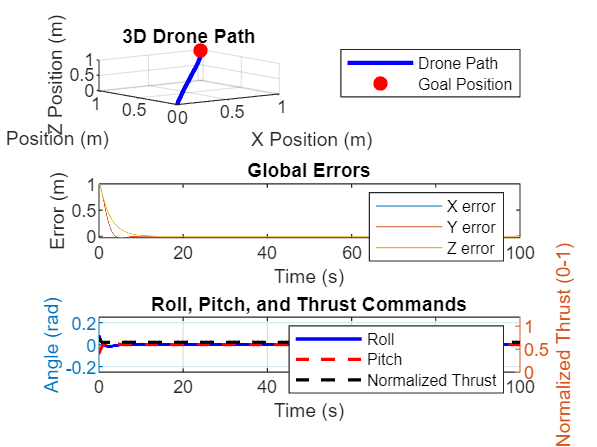


% === Plotting ===
figure;

% 3D plot of the drone's movement
subplot(3, 1, 1);
plot3(position_log(:,1), position_log(:,2), position_log(:,3), 'b-', 'LineWidth', 2);
hold on;
plot3(goal_position(1), goal_position(2), goal_position(3), 'ro', 'MarkerFaceColor', 'r');
title('3D Drone Path');
xlabel('X Position (m)');
ylabel('Y Position (m)');
zlabel('Z Position (m)');
legend('Drone Path', 'Goal Position');
grid on;

% Plot Global Errors
subplot(3, 1, 2);
plot(time, errors_global);
title('Global Errors');
xlabel('Time (s)');
ylabel('Error (m)');
legend('X error', 'Y error', 'Z error');

% Plot Roll, Pitch, and Normalized Thrust Commands
subplot(3, 1, 3);
yyaxis left
plot(time, roll_pitch_values(:,1), 'b', 'LineWidth', 1.5); hold on;
plot(time, roll_pitch_values(:,2), 'r', 'LineWidth', 1.5);
ylabel('Angle (rad)');
ylim([-0.25, 0.25]);

yyaxis right
plot(time, thrust_values / 15, 'k--', 'LineWidth', 1.5);
ylabel('Normalized Thrust (0-1)');
ylim([0 1.2]);

xlabel('Time (s)');
title('Roll, Pitch, and Thrust Commands');
legend('Roll', 'Pitch', 'Normalized Thrust');
grid on;